# **HW10**

# Q1

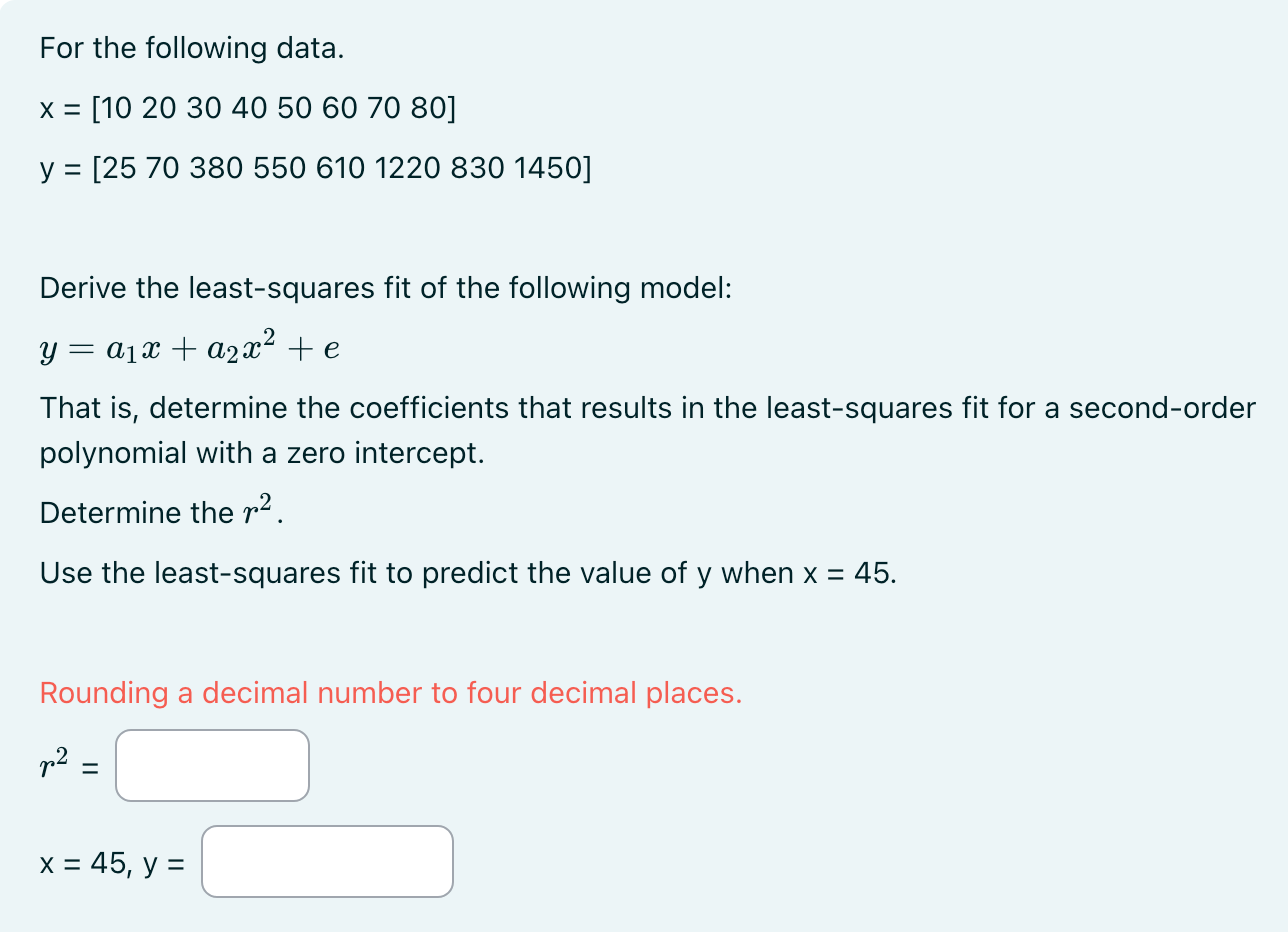

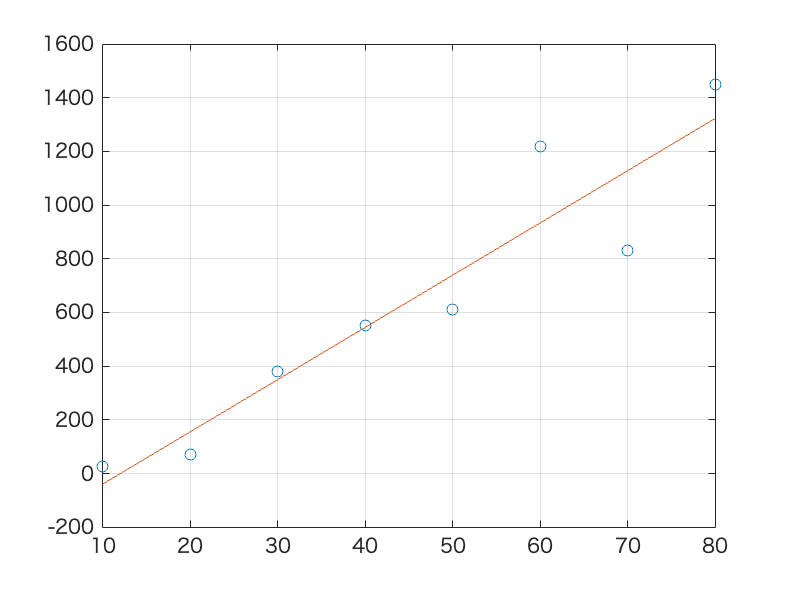

a =    19.4702 -234.2857


r2 = 0.8805

x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];

[a, r2] = linregr(x, y)

p2 = polyfit(x, y, 2)

p2 =     0.0372   16.1220 -178.4821



xtest = 45

xtest = 45

ytest = polyval(p2, xtest)

ytest = 622.3438

# Q2

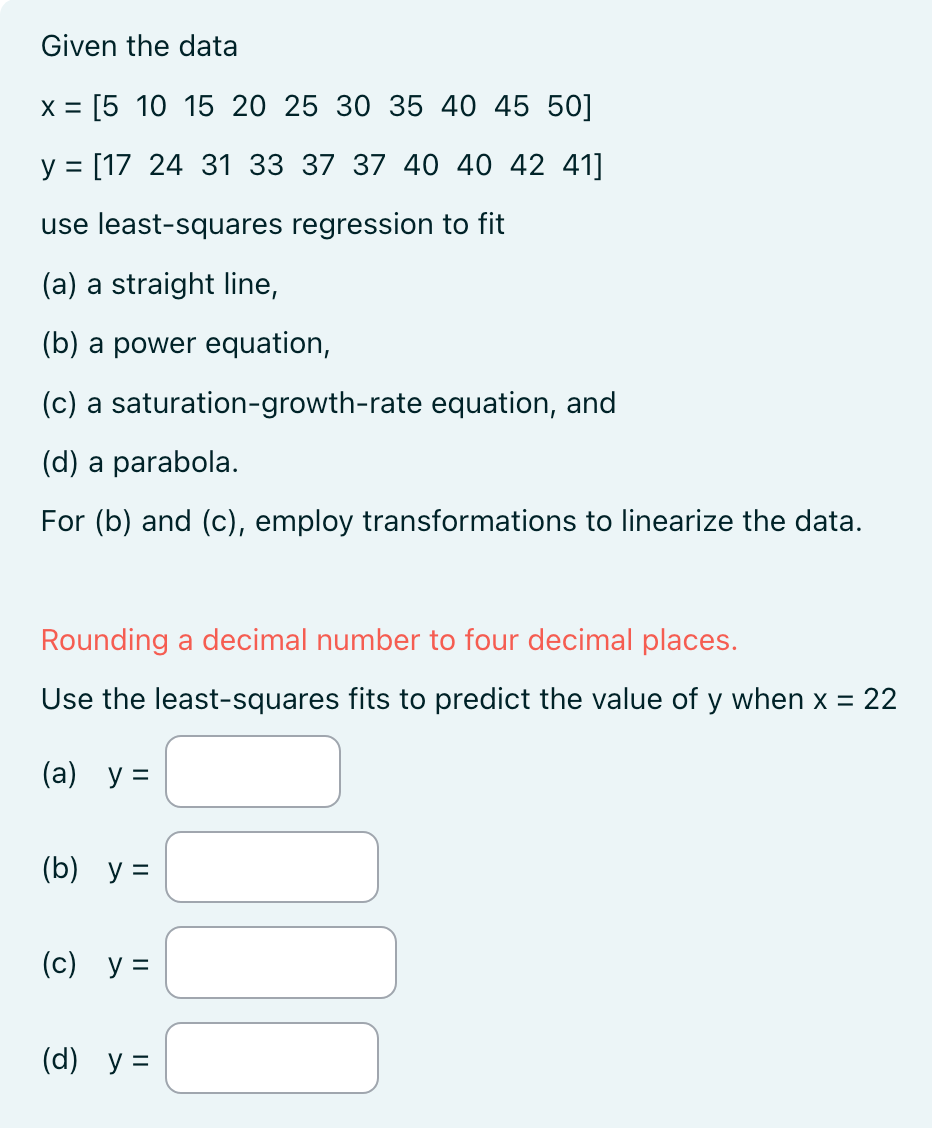

% linear (straight line) fit
x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];
xtest = 22

xtest = 22

p1 = polyfit(x, y, 1)

p1 =     0.4945   20.6000


yy1 = polyval(p1, x)

yy1 =    23.0727   25.5455   28.0182   30.4909   32.9636   35.4364   37.9091   40.3818   42.8545   45.3273


ytest1 = polyval(p1, xtest)

ytest1 = 31.4800


% power equation fit
new_power_x = log10(x)

new_power_x =     0.6990    1.0000    1.1761    1.3010    1.3979    1.4771    1.5441    1.6021    1.6532    1.6990


new_power_y = log10(y)

new_power_y =     1.2304    1.3802    1.4914    1.5185    1.5682    1.5682    1.6021    1.6021    1.6232    1.6128


p2 = polyfit(new_power_x, new_power_y, 2)

p2 =    -0.2541    1.0062    0.6460


yy2 = polyval(p2, x)

yy2 =    -0.6746  -14.6983  -41.4250  -80.8548 -132.9877 -197.8236 -275.3626 -365.6047 -468.5498 -584.1980


ytest2 = polyval(p2, xtest)

ytest2 = -100.1836

### `linregr`

function [a, r2] = linregr(x,y)
    % linregr: linear regression curve fitting
    % [a, r2] = linregr(x,y): Least squares fit of straight
    % line to data by solving the normal equations
    % input:
    % x = independent variable
    % y = dependent variable
    % output:
    % a = vector of slope, a(1), and intercept, a(2)
    % r2 = coefficient of determination
    n = length(x);
    if length(y)~=n, error('x and y must be same length'); end
    x = x(:); y = y(:); % convert to column vectors
    sx = sum(x); sy = sum(y);
    sx2 = sum(x.*x); sxy = sum(x.*y); sy2 = sum(y.*y);
    a(1) = (n*sxy-sx*sy)/(n*sx2-sx^2);
    a(2) = sy/n-a(1)*sx/n;
    r2 = ((n*sxy-sx*sy)/sqrt(n*sx2-sx^2)/sqrt(n*sy2-sy^2))^2;
    % create plot of data and best fit line
    xp = linspace(min(x),max(x),2);
    yp = a(1)*xp+a(2);
    plot(x,y,'o',xp,yp)
    grid on
end